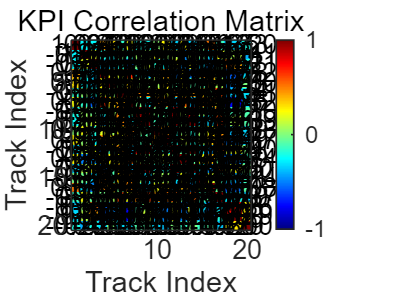

%% %%%%  Hw3-Part1-3)b  %%%%%%%%%
clear; clc; close all;

% 加载数据
load('GoogleDataset.mat');  % 确保数据文件存在

% 选取 Click 指标的控制 KPI（1:19列）
all_KPI = [Click', Cost', Conversion']';

% 归一化（分别归一化）
for i = 1:size(all_KPI, 1)
    all_KPI(i, :) = (all_KPI(i, :) - mean(all_KPI(i, :))) / std(all_KPI(i, :));
end
num_tracks = size(all_KPI, 2); % 轨迹数量（19个企业）

%% **Step 1: 计算 Pearson 相关性矩阵**
corr_matrix = corrcoef(all_KPI);  

% **Step 2: 画相关性热力图**
figure;
imagesc(corr_matrix);  % 画相关性矩阵
colorbar;              % 添加颜色条
colormap(jet);         % 设置颜色映射
clim([-1 1]);         % 颜色范围 (-1 to 1)
title('KPI Correlation Matrix');
xlabel('Track Index');
ylabel('Track Index');

% **Step 3: 添加数值标注**
[num_rows, num_cols] = size(corr_matrix);
for i = 1:num_rows
    for j = 1:num_cols
        text(j, i, sprintf('%.2f', corr_matrix(i, j)), ...
            'HorizontalAlignment', 'center', 'FontSize', 8, 'Color', 'k');
    end
end

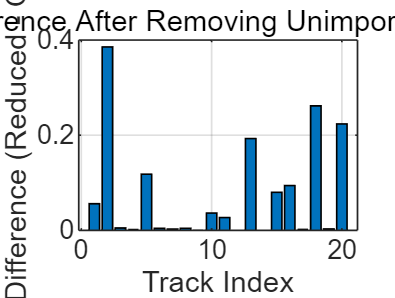


%% **Step 4: 计算 MSE 并去除无用列**
threshold = 0.1;  % 设定相关性阈值（绝对值小于此值的变量认为无用）
MSE_original = zeros(1, num_tracks);
MSE_reduced = zeros(1, num_tracks);

for i = 1:num_tracks
    target_idx = i;  
    predictor_idx = setdiff(1:num_tracks, target_idx); % 预测变量索引

    % **1. 计算原始 MSE（使用所有变量）**
    X_train = all_KPI(:, predictor_idx);
    y_train = all_KPI(:, target_idx);
    beta = (X_train' * X_train) \ (X_train' * y_train);
    y_pred = X_train * beta;
    MSE_original(i) = mean((y_train - y_pred).^2);

    % **2. 找出与目标 KPI 低相关的变量并去除**
    corr_with_target = abs(corr_matrix(target_idx, predictor_idx));
    useful_vars = predictor_idx(corr_with_target >= threshold); % 仅保留相关性高的

    % **3. 计算 Reduced MSE（去除无用变量后）**
    if isempty(useful_vars)
        MSE_reduced(i) = NaN;  % 若所有变量都被去除，则跳过
    else
        X_reduced = all_KPI(:, useful_vars);
        beta_reduced = (X_reduced' * X_reduced) \ (X_reduced' * y_train);
        y_pred_reduced = X_reduced * beta_reduced;
        MSE_reduced(i) = mean((y_train - y_pred_reduced).^2);
    end
end

%% **Step 5: 绘制 MSE 差值图**
MSE_diff = MSE_reduced - MSE_original;  % 计算 MSE 变化（去除无用变量后）

figure;
bar(MSE_diff);
xlabel('Track Index');
ylabel('MSE Difference (Reduced - Original)');
title('MSE Difference After Removing Unimportant Variables');
grid on;